# 储能优化规划与运行课程设计：第二周任务四

姓名：严军涛；学号：209230538；班级：储能231。 基于课程 Interactive04 与 Template_Week2：无光伏的纯负荷馈线， 五组配对功率/容量档位，Big-M 线性化、LinDistFlow MILP、交流潮流回代。 先将 MATPOWER、YALMIP 及 ESS-Course-Materials/interactive、cases 加入路径。 全部运行后，结果、配置表、灵敏度表及 PNG/PDF/FIG 写入本文件所在目录。

submission_dir=fileparts(mfilename('fullpath'));
Stu_ID=209230538;
assert(exist('runpf','file')==2 && exist('sdpvar','file')==2,...
 '请先配置 MATPOWER 与 YALMIP。');
assert(exist('ess_live_setup','file')==2,'请将课程 interactive 与 cases 添加到 MATLAB 路径。');

## 基准规划与年综合费用

目标 min C_inv+C_om+C_grid；CRF=0.080242587，D=365 天。 cP=80000 元/MW，cE=550000 元/MWh，cOM=200000 元/(MW·年)。 每处至多选择 (1,1)、(2,2)、(3,3)、(4,4)、(5,5) MW/MWh 一档。 效率为 0.90/0.95，SoC∈[0.20,0.80]，初末均为 0.50。

V_min_Lin=0.96;energy_cost_multiplier=1.0;
R=ess_yan_week2_plan(V_min_Lin,energy_cost_multiplier);

    StudentID           Case          LoadMultiplier    CandidateBuses
    __________    ________________    ______________    ______________

    2.0923e+08    "case_kaifaqu_A"        1.076          "[5 11 16]"  


================ 第二周：储能选址定容与交流潮流验证报告 ================
候选节点  5: 选址状态 z=0 | 额定功率 = 0 MW | 额定容量 = 0 MWh
候选节点 11: 选址状态 z=1 | 额定功率 = 1 MW | 额定容量 = 1 MWh
候选节点 16: 选址状态 z=1 | 额定功率 = 1 MW | 额定容量 = 1 MWh
年化投资成本: 10.11 万元 | 年运维成本: 40.00 万元 | 年网损降低收益: 0.82 万元
LinDistFlow 最低电压: 0.9600 p.u. | 交流潮流最低电压: 0.9589 p.u. | 最大电压偏差: 0.0011 p.u.
    Node    Installed    RatedPower_MW    RatedEnergy_MWh
    ____    _________    _____________    _______________

      5         0              0                 0       
     11         1              1                 1       
     16         1              1                 1       

    AC_MinVoltage    AC_MaxVoltage    max_voltage_error_pu    B_loss_ann
    _____________    _____________    ____________________    __________

       0.95891      

assert(~R.Infeasible && R.Checks.ModelPassed && R.Checks.ACVoltagePassed,...
 '基准规划或交流潮流核验未通过。');
disp(R.Configuration);disp(R.Checks);

    Node    Installed    RatedPower_MW    RatedEnergy_MWh
    ____    _________    _____________    _______________

      5         0              0                 0       
     11         1              1                 1       
     16         1              1                 1       

    MinConstraintResidual: -1.5738e-13
          MaxIntegerError: 5.3905e-14
        MaxSimultaneousMW: 0
     MaxDeltaProductError: 4.0079e-14
           MaxEnergyError: 1.5743e-13
         TerminalSoCError: 0
             MinACVoltage: 0.9589
             MaxACVoltage: 1
          ACVoltagePassed: 1
              ModelPassed: 1



CostBreakdown=table(R.AnnualInvestment,R.AnnualOM,R.AnnualGridLin,R.AnnualTotalLin,...
 R.AnnualGridAC,R.AnnualTotalAC,R.AnnualGridBaseAC,R.NetAnnualSavingAC,...
 'VariableNames',{'Investment_YuanPerYear','OM_YuanPerYear','GridLin_YuanPerYear',...
 'TotalLin_YuanPerYear','GridAC_YuanPerYear','TotalAC_YuanPerYear',...
 'BaseGridAC_YuanPerYear','NetSavingAC_YuanPerYear'});
disp(CostBreakdown);

    Investment_YuanPerYear    OM_YuanPerYear    GridLin_YuanPerYear    TotalLin_YuanPerYear    GridAC_YuanPerYear    TotalAC_YuanPerYear    BaseGridAC_YuanPerYear    NetSavingAC_YuanPerYear
    ______________________    ______________    ___________________    ____________________    __________________    ___________________    ______________________    _______________________

          1.0111e+05              4e+05              1.565e+07              1.6151e+07             1.5935e+07            1.6436e+07               1.619e+07                 -2.4628e+05      



## 参数灵敏度：电压下限裕度与单位能量投资费用

网络、负荷、候选位置与其他设备参数保持不变。 对不可行场景保留 intlinprog 的不可行状态；不使用其未定义的配置与成本。

settings=[.95 1;.955 1;.96 1;.965 1;.97 1;.96 .5;.96 1.5;.96 2];
Sensitivity=cell(size(settings,1),1);
Feasible=false(size(settings,1),1);ACPassed=Feasible;
InstalledNodes=strings(size(settings,1),1);PowerMW=nan(size(Feasible));EnergyMWh=PowerMW;
TotalLin=PowerMW;MinAC=PowerMW;NetSavingAC=PowerMW;
for n=1:size(settings,1)
 if isequal(settings(n,:),[V_min_Lin energy_cost_multiplier])
  Q=R;
 else
  evalc('Q=ess_yan_week2_plan(settings(n,1),settings(n,2));');
 end
 Sensitivity{n}=Q;
 if ~Q.Infeasible
  Feasible(n)=true;ACPassed(n)=Q.Checks.ACVoltagePassed;
  InstalledNodes(n)=string(mat2str(Q.Candidate_Buses(round(Q.z)==1)));
  PowerMW(n)=sum(Q.Configuration.RatedPower_MW);EnergyMWh(n)=sum(Q.Configuration.RatedEnergy_MWh);
  TotalLin(n)=Q.AnnualTotalLin;MinAC(n)=Q.Checks.MinACVoltage;NetSavingAC(n)=Q.NetAnnualSavingAC;
 else
  InstalledNodes(n)="不可行";
 end
end
SensitivityTable=table(settings(:,1),settings(:,2),Feasible,InstalledNodes,PowerMW,EnergyMWh,...
 TotalLin,MinAC,ACPassed,NetSavingAC,'VariableNames',{'VminLin','EnergyCostMultiplier',...
 'Feasible','InstalledNodes','TotalPower_MW','TotalEnergy_MWh','AnnualTotalLin_Yuan',...
 'MinACVoltage','ACVoltagePassed','NetAnnualSavingAC_Yuan'});
disp(SensitivityTable);

    VminLin    EnergyCostMultiplier    Feasible    InstalledNodes    TotalPower_MW    TotalEnergy_MWh    AnnualTotalLin_Yuan    MinACVoltage    ACVoltagePassed    NetAnnualSavingAC_Yuan
    _______    ____________________    ________    ______________    _____________    _______________    ___________________    ____________    _______________    ______________________

      0.95               1              true        "zeros(1,0)"            0                 0              1.5897e+07           0.95502            true                         0      
     0.955               1              true        "zeros(1,0)"            0                 0              1.5897e+07           0.95502            true                         0      
      0.96               1              true        "[11 16]"               2                 2              1.6151e+07           0.95891            true               -2.4628e+05      
     0.965               1              false       "不可行"            

## 保存完整原始结果与课程标准六字段

Result.StuID=Stu_ID;Result.Obj_Value=R.AnnualTotalLin;
Result.Opt_Sites=find(round(R.z)==1); % 候选位置序号，通过 Candidate_Buses 映射为实际母线。
Result.Opt_P_rated=R.Configuration.RatedPower_MW;
Result.Opt_E_rated=R.Configuration.RatedEnergy_MWh;Result.Max_V_Err=R.MaxVoltageError;
summary_path=fullfile(submission_dir,'result_summary.mat');
if isfile(summary_path)
 previous=load(summary_path);
 if isfield(previous,'result_summary'),result_summary=previous.result_summary;else,result_summary=struct;end
else,result_summary=struct;end
result_summary.StudentID=Stu_ID;result_summary.Name='严军涛';result_summary.Class='储能231';
result_summary.Task4=R;result_summary.Task4Sensitivity=Sensitivity;
result_summary.Task4SensitivityTable=SensitivityTable;
result_summary.Candidate_Buses=R.Candidate_Buses;
save(summary_path,'Result','result_summary');
save(fullfile(submission_dir,'Week2_Planning_raw.mat'),'R','Sensitivity','SensitivityTable','CostBreakdown');
writetable(R.Configuration,fullfile(submission_dir,'Week2_Configuration.csv'));
writetable(CostBreakdown,fullfile(submission_dir,'Week2_Costs.csv'));
writetable(SensitivityTable,fullfile(submission_dir,'Week2_Sensitivity.csv'));

## 原生绘图与图表导出

五幅图分别给出配置及成本、交流电压、逐时运行、参数灵敏度和网络位置。 白底 PNG 600 dpi，原生矢量 PDF 与可编辑曲线 FIG。

useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


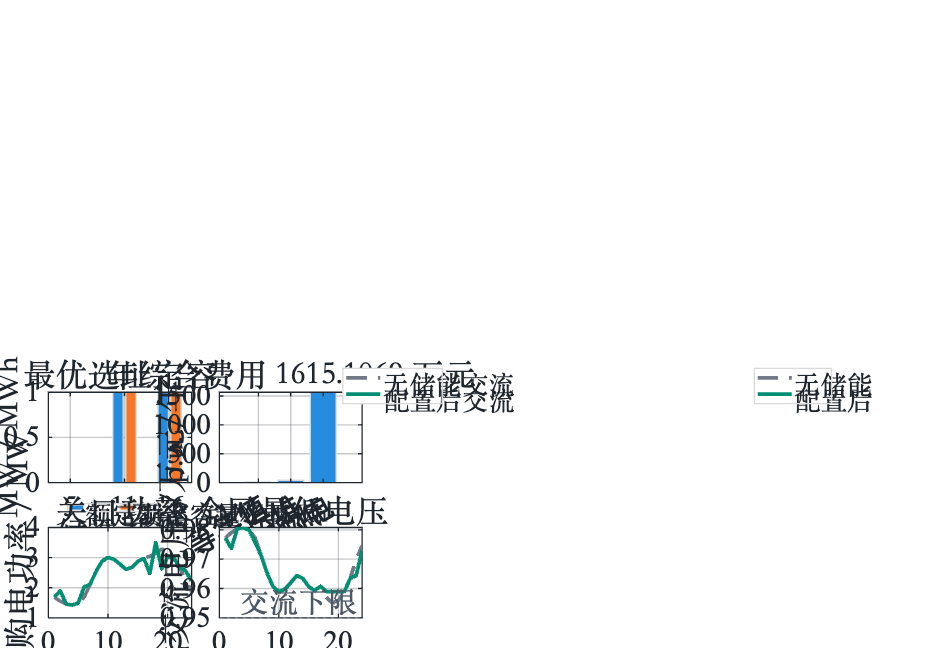

useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


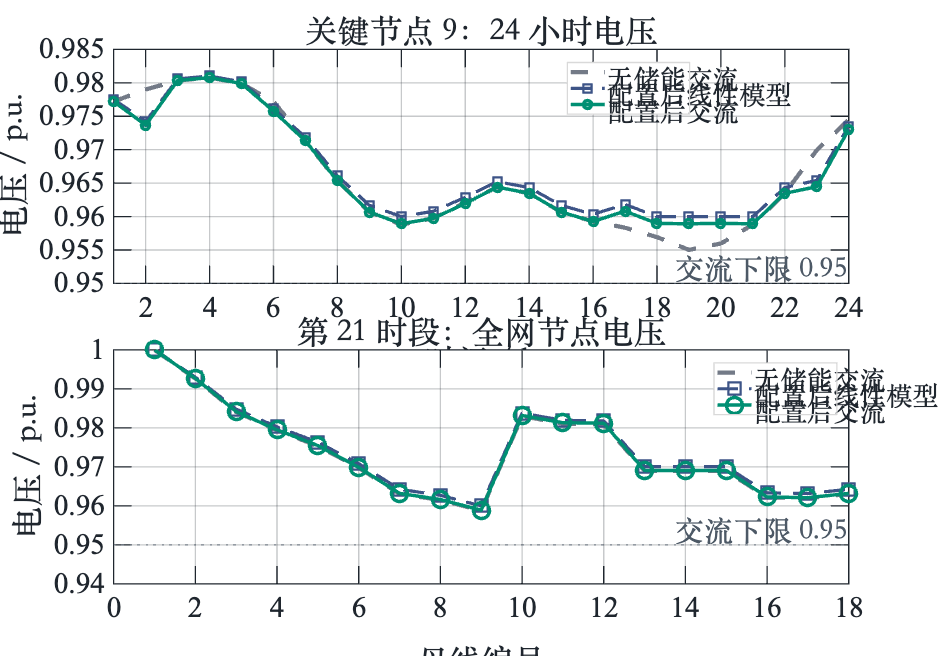

useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


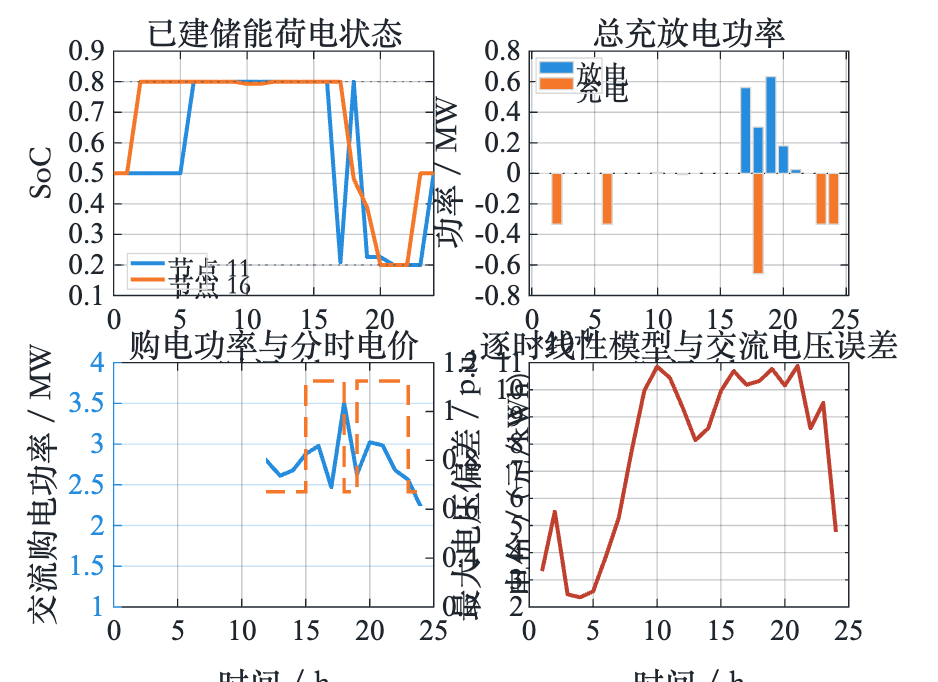

useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


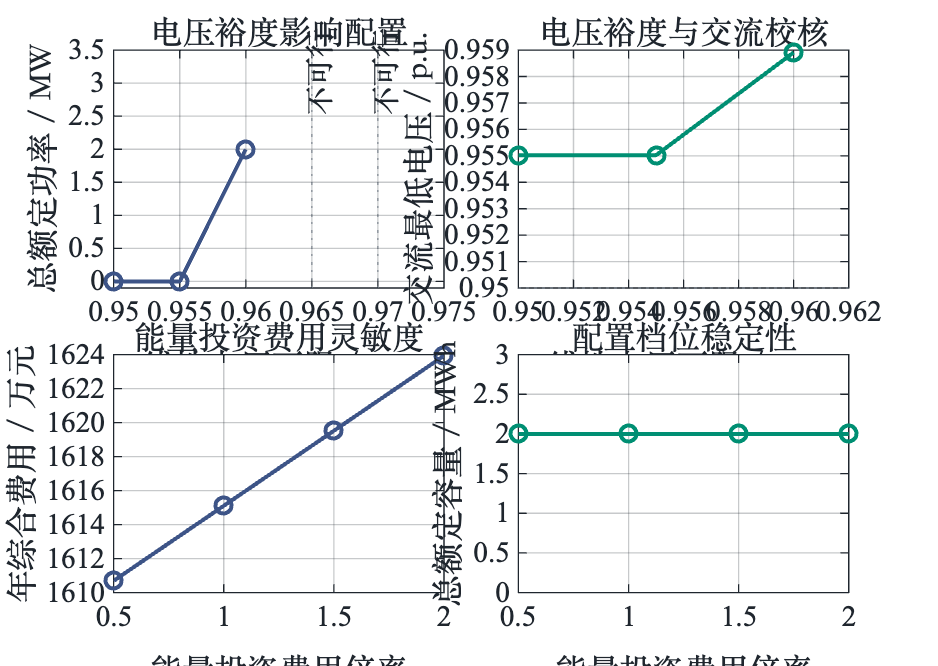

useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


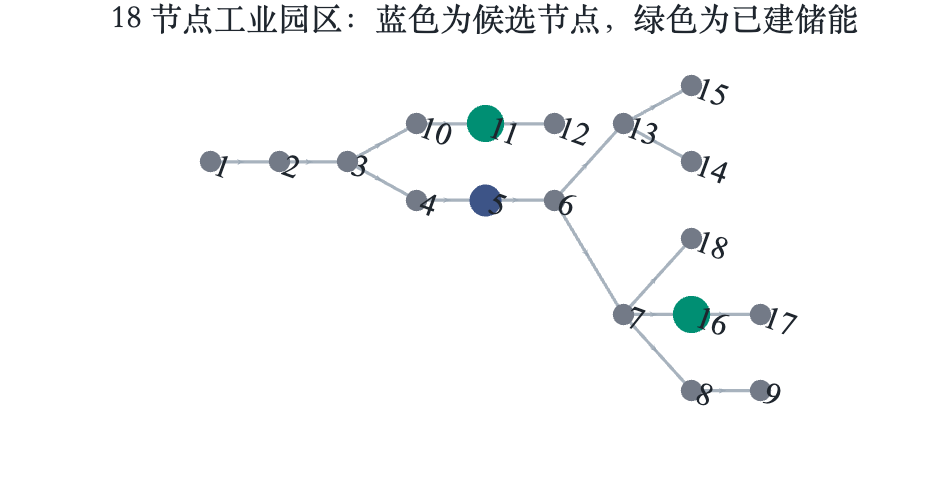

ess_yan_week2_figures(R,SensitivityTable,submission_dir);

fprintf('任务四完成：%s；候选位置序号 %s；实际母线 %s。\n',R.Case,...
 mat2str(Result.Opt_Sites'),mat2str(R.Candidate_Buses(Result.Opt_Sites)));

任务四完成：case_kaifaqu_A；候选位置序号 [2 3]；实际母线 [11 16]。


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


useCS = logical
   1


## 局部函数：完整选址定容 MILP 模型

function R=ess_yan_week2_plan(v_min,energy_multiplier)
% 与 Interactive04 一致的五档储能规划模型；参数为线性电压下限与能量投资费用倍率。
% # 交互教学 04：储能选址定容与交流潮流验证
% 本节采用无光伏注入的纯负荷馈线。储能按五种功率/能量配置方案选择，采用大M法和 LinDistFlow 建立 MILP，再代入交流潮流计算。

lesson = ess_live_setup();

## 个人学号与本次计算条件 修改学号后重新运行后续各节。算例、负荷系数和候选节点沿用课程统一规则。

Stu_ID = 209230538;
XY=mod(Stu_ID,100);
X_digit=floor(XY/10); Y_digit=mod(XY,10);
alpha=1+0.002*XY;
if ismember(Y_digit,[0 1 2 3])
    case_name='case_nongcun';
elseif ismember(Y_digit,[4 5 6])
    case_name='case_chengshi_A';
else
    case_name='case_kaifaqu_A';
end
if ismember(X_digit,[0 1 2])
    study_buses=[4 9 14];
elseif ismember(X_digit,[3 4 5])
    study_buses=[5 11 16];
else
    study_buses=[6 13 17];
end
profiles=load(fullfile(lesson.cases,'profiles_24h.mat'));
T=profiles.T; dt=1;
load_curve_pu=profiles.load_curve_pu; pv_curve_pu=profiles.pv_curve_pu;
price_MWh=profiles.price_MWh; price_kWh=profiles.price_kWh;
disp(table(Stu_ID,string(case_name),alpha,string(mat2str(study_buses)),...
    'VariableNames',{'StudentID','Case','LoadMultiplier','CandidateBuses'}));
mpc=loadcase(case_name);
cand_buses=study_buses;N_cand=numel(cand_buses);
yalmip('clear');

## 配置方案与经济参数 五种配置方案按相同档位选择功率与能量容量。初末荷电状态为 0.50，运行范围为 0.20 至 0.80。

P_opt_MW  = [1, 2, 3, 4, 5];
E_opt_MWh = [1, 2, 3, 4, 5];
K = length(E_opt_MWh);
eta_ch  = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0   = 0.50;
c_P    = 0.08 * 1e6;
c_E    = 0.55 * 1e6;
c_om   = 200 * 1e3;
Y_life = 20;
d_rate = 0.05;
CRF    = (d_rate * (1 + d_rate)^Y_life) / ((1 + d_rate)^Y_life - 1);
D_days = 365;
V_min_Lin = v_min;
V_max_Lin = 1.050;

## 电压裕度与投资费用试验 默认参数与课程参考模型一致。修改线性模型电压下限或能量投资费用倍率后，重新运行后续模型及交流潮流计算。

V_min_Lin = v_min;
energy_cost_multiplier = energy_multiplier;
c_E=0.55*1e6*energy_cost_multiplier;

## 构造逐时负荷与网络参数 网络采用标幺值，储能充放电功率采用 MW。

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br  = size(mpc.branch, 1);
fbus  = mpc.branch(:, 1);
tbus  = mpc.branch(:, 2);
r_br  = mpc.branch(:, 3);
x_br  = mpc.branch(:, 4);
Pd_pu = (mpc.bus(:, 3) * alpha / Sbase) * load_curve_pu';
Qd_pu = (mpc.bus(:, 4) * alpha / Sbase) * load_curve_pu';

## 声明选址、配置与运行变量 z 表示建站，w 表示配置选择，delta 按候选节点、配置方案、时段排列。

z        = binvar(N_cand, 1, 'full');
w        = binvar(N_cand, K, 'full');
SoC      = sdpvar(N_cand, T, 'full');
delta    = sdpvar(N_cand, K, T, 'full');
P_ch_MW  = sdpvar(N_cand, T, 'full');
P_dis_MW = sdpvar(N_cand, T, 'full');
u_ch     = binvar(N_cand, T, 'full');
U_lin     = sdpvar(N_bus, T, 'full');
P_br      = sdpvar(N_br,  T, 'full');
Q_br      = sdpvar(N_br,  T, 'full');
P_grid_pu = sdpvar(1,     T, 'full');
Q_grid_pu = sdpvar(1,     T, 'full');

## 构造配置选择与储能运行约束 逐项对应配置选择、四条大M约束、初末状态及能量平衡。

%{"align":"center"} $\\sum\_k E\_k^{\\mathrm{opt}}(\\delta\_{i,k,t}-\\delta\_{i,k,t-1})=(\\eta\_{\\mathrm{ch}}P\_{i,t}^{\\mathrm{ch}}-P\_{i,t}^{\\mathrm{dis}}/\\eta\_{\\mathrm{dis}})\\Delta t$

## 大M法的下界与上界（一） 配置未选择时，以下约束使辅助变量为零。

%{"align":"center"} $\\mathrm{SoC}\_{\\min}w\_{i,k}\\le\\delta\_{i,k,t}\\le\\mathrm{SoC}\_{\\max}w\_{i,k}$

## 大M法的下界与上界（二） 配置被选择时，以下约束使辅助变量等于荷电状态。

%{"align":"center"} $\\mathrm{SoC}\_{i,t}-\\mathrm{SoC}\_{\\max}(1-w\_{i,k})\\le\\delta\_{i,k,t}\\le\\mathrm{SoC}\_{i,t}-\\mathrm{SoC}\_{\\min}(1-w\_{i,k})$
Constraints = [];
P_rated     = w * P_opt_MW';
E_rated     = w * E_opt_MWh';
P_rated_MW  = P_rated;
E_rated_MWh = E_rated;
P_max_bound = max(P_opt_MW);
for idx = 1:N_cand
    Constraints = [Constraints, sum(w(idx, :)) == z(idx)];
    Constraints = [Constraints, SoC_min <= SoC(idx, :) <= SoC_max];
    Constraints = [Constraints, SoC(idx, T) == SoC_0];
    Constraints = [Constraints, 0 <= P_ch_MW(idx, :)  <= P_rated_MW(idx)];
    Constraints = [Constraints, 0 <= P_dis_MW(idx, :) <= P_rated_MW(idx)];
    Constraints = [Constraints, P_ch_MW(idx, :)  <= u_ch(idx, :) * P_max_bound];
    Constraints = [Constraints, P_dis_MW(idx, :) <= (1 - u_ch(idx, :)) * P_max_bound];
    for k = 1:K
        d_vec = reshape(delta(idx, k, :), 1, T);
        Constraints = [Constraints, SoC_min * w(idx, k) <= d_vec <= SoC_max * w(idx, k)];
        Constraints = [Constraints, SoC(idx, :) - SoC_max * (1 - w(idx, k)) <= d_vec <= ...
            SoC(idx, :) - SoC_min * (1 - w(idx, k))];
    end
    for t = 1:T
        if t == 1
            E_prev = E_opt_MWh * (SoC_0 * w(idx, :))';
        else
            E_prev = E_opt_MWh * reshape(delta(idx, :, t - 1), K, 1);
        end
        E_curr = E_opt_MWh * reshape(delta(idx, :, t), K, 1);
        Constraints = [Constraints, E_curr - E_prev == ...
            eta_ch * P_ch_MW(idx, t) - P_dis_MW(idx, t) / eta_dis];
    end
end

## 构造 LinDistFlow 与节点电压约束 对照上一讲支路潮流方程，确认模型中省略的支路损耗项。

%{"align":"center"} $U\_{j,t}=U\_{i,t}-2(r\_{ij}P\_{ij,t}+x\_{ij}Q\_{ij,t})$
A_from  = sparse(fbus, 1:N_br, 1, N_bus, N_br);
A_to    = sparse(tbus, 1:N_br, 1, N_bus, N_br);
A_cand  = sparse(cand_buses, 1:N_cand, 1, N_bus, N_cand);
A_slack = sparse(1, 1, 1, N_bus, 1);
Constraints = [Constraints, A_to * P_br - A_from * P_br + A_slack * P_grid_pu + ...
    A_cand * ((P_dis_MW - P_ch_MW) / Sbase) == Pd_pu];
Constraints = [Constraints, A_to * Q_br - A_from * Q_br + A_slack * Q_grid_pu == Qd_pu];
Constraints = [Constraints, U_lin(1, :) == 1.0];
Constraints = [Constraints, (V_min_Lin^2) <= U_lin(2:end, :) <= (V_max_Lin^2)];
for b = 1:N_br
    Constraints = [Constraints, U_lin(tbus(b), :) == U_lin(fbus(b), :) - ...
        2 * (r_br(b) * P_br(b, :) + x_br(b) * Q_br(b, :))];
end

## 建立年综合费用并求解 费用包括投资等年值、年运维费用和按典型日折算的年购电费用。

C_inv_ann  = CRF * sum(c_P * P_rated_MW + c_E * E_rated_MWh);
C_om_ann   = sum(c_om * P_rated_MW);
C_grid_ann = D_days * sum((Sbase * P_grid_pu') .* price_MWh);
Objective  = C_inv_ann + C_om_ann + C_grid_ann;
solver_name='intlinprog';
ops=sdpsettings('solver',solver_name,'verbose',0,'savesolveroutput',1);
ops.intlinprog.RelativeGapTolerance=1e-6;
ops.intlinprog.AbsoluteGapTolerance=1e-8;
tic;sol=optimize(Constraints,Objective,ops);solve_seconds=toc;
if sol.problem==1
 R=struct('VminLin',V_min_Lin,'EnergyCostMultiplier',energy_cost_multiplier,...
  'Infeasible',true,'Solution',sol);return;
end
assert(sol.problem==0,'规划求解失败：%s',sol.info);

## 将最优充放电计划代入交流潮流 无储能和配置后方案使用相同负荷。逐时检查交流潮流收敛，再比较节点电压和有功损耗。

V_lin_pu      = sqrt(value(U_lin));
V_ac_base     = zeros(N_bus, T);
Pgrid_ac_base=zeros(T,1);Pgrid_ac_ess=zeros(T,1);
V_ac_ess      = zeros(N_bus, T);
Ploss_ac_base = zeros(T, 1);
Ploss_ac_ess  = zeros(T, 1);
P_net_ess_MW  = value(P_dis_MW - P_ch_MW);
mpopt = mpoption('verbose', 0, 'out.all', 0);
for t = 1:T
    mpc_b = mpc;
    mpc_b.bus(:, 3) = Pd_pu(:, t) * Sbase;
    mpc_b.bus(:, 4) = Qd_pu(:, t) * Sbase;
    res_b = runpf(mpc_b, mpopt);
    assert(res_b.success==1,'无储能方案第 %d 时段潮流未收敛。',t);
    V_ac_base(:, t)  = res_b.bus(:, 8);
    Pgrid_ac_base(t)=sum(res_b.gen(:,2));
    Ploss_ac_base(t) = sum(real(get_losses(res_b)));
    mpc_e = mpc_b;
    mpc_e.bus(cand_buses, 3) = mpc_e.bus(cand_buses, 3) - P_net_ess_MW(:, t);
    res_e = runpf(mpc_e, mpopt);
    assert(res_e.success==1,'配置后第 %d 时段潮流未收敛。',t);
    V_ac_ess(:, t)  = res_e.bus(:, 8);
    Pgrid_ac_ess(t)=sum(res_e.gen(:,2));
    Ploss_ac_ess(t) = sum(real(get_losses(res_e)));
end
B_loss_ann           = D_days * sum((Ploss_ac_base - Ploss_ac_ess) .* price_MWh);
max_voltage_error_pu = max(max(abs(V_lin_pu - V_ac_ess)));
fprintf('\n================ 第二周：储能选址定容与交流潮流验证报告 ================\n');
for idx = 1:N_cand
    fprintf('候选节点 %2d: 选址状态 z=%d | 额定功率 = %d MW | 额定容量 = %d MWh\n', ...
        cand_buses(idx), round(value(z(idx))), round(value(P_rated_MW(idx))), round(value(E_rated_MWh(idx))));
end
fprintf('年化投资成本: %.2f 万元 | 年运维成本: %.2f 万元 | 年网损降低收益: %.2f 万元\n', ...
    value(C_inv_ann) / 1e4, value(C_om_ann) / 1e4, B_loss_ann / 1e4);
fprintf('LinDistFlow 最低电压: %.4f p.u. | 交流潮流最低电压: %.4f p.u. | 最大电压偏差: %.4f p.u.\n', ...
    min(V_lin_pu(:)), min(V_ac_ess(:)), max_voltage_error_pu);

## 配置方案与交流潮流结果 配置表使用实际节点编号。标准结果文件中的 Opt_Sites 保留课程既有的候选节点序号定义。

Configuration=table(cand_buses(:),round(value(z)),value(P_rated_MW),value(E_rated_MWh),...
 'VariableNames',{'Node','Installed','RatedPower_MW','RatedEnergy_MWh'});
disp(Configuration);
AC_MinVoltage=min(V_ac_ess(:));AC_MaxVoltage=max(V_ac_ess(:));
disp(table(AC_MinVoltage,AC_MaxVoltage,max_voltage_error_pu,B_loss_ann));

R=struct('Infeasible',false,'StudentID',Stu_ID,'Name','严军涛','Class','储能231','Case',case_name,...
 'Alpha',alpha,'Candidate_Buses',cand_buses,'Sbase',Sbase,'T',T,'dt',dt,...
 'VminLin',V_min_Lin,'VmaxLin',V_max_Lin,'EnergyCostMultiplier',energy_cost_multiplier,...
 'POptionsMW',P_opt_MW,'EOptionsMWh',E_opt_MWh,'eta_ch',eta_ch,'eta_dis',eta_dis,...
 'SoCmin',SoC_min,'SoCmax',SoC_max,'SoC0',SoC_0,'cP',c_P,'cE',c_E,'cOM',c_om,...
 'LifeYears',Y_life,'DiscountRate',d_rate,'CRF',CRF,'Days',D_days,...
 'mpc',mpc,'PloadMW',Pd_pu*Sbase,'QloadMvar',Qd_pu*Sbase,'PriceMWh',price_MWh,...
 'z',value(z),'w',value(w),'SoC',value(SoC),'delta',value(delta),'u',value(u_ch),...
 'PchMW',value(P_ch_MW),'PdisMW',value(P_dis_MW),'Ulin',value(U_lin),...
 'Pbranch',value(P_br),'Qbranch',value(Q_br),'PgridLinMW',value(P_grid_pu)*Sbase,...
 'Vlin',V_lin_pu,'VACBase',V_ac_base,'VACStorage',V_ac_ess,...
 'LossBaseMW',Ploss_ac_base,'LossStorageMW',Ploss_ac_ess,...
 'PgridACBaseMW',Pgrid_ac_base,'PgridACStorageMW',Pgrid_ac_ess,...
 'Configuration',Configuration,'AnnualInvestment',value(C_inv_ann),'AnnualOM',value(C_om_ann),...
 'AnnualGridLin',value(C_grid_ann),'AnnualTotalLin',value(Objective),...
 'AnnualGridAC',D_days*sum(price_MWh.*Pgrid_ac_ess),...
 'AnnualGridBaseAC',D_days*sum(price_MWh.*Pgrid_ac_base),...
 'AnnualLossBenefit',B_loss_ann,'MaxVoltageError',max_voltage_error_pu,...
 'Solver',solver_name,'SolveSeconds',solve_seconds,'Solution',sol);
R.AnnualTotalAC=R.AnnualInvestment+R.AnnualOM+R.AnnualGridAC;
R.NetAnnualSavingAC=R.AnnualGridBaseAC-R.AnnualTotalAC;
checkres=check(Constraints);R.Checks.MinConstraintResidual=min(checkres);
R.Checks.MaxIntegerError=max(abs([R.z(:);R.w(:);R.u(:)]-round([R.z(:);R.w(:);R.u(:)])));
R.Checks.MaxSimultaneousMW=max(min(R.PchMW,R.PdisMW),[],'all');
R.Checks.MaxDeltaProductError=max(abs(R.delta-reshape(R.w,N_cand,K,1).*reshape(R.SoC,N_cand,1,T)),[],'all');
E=reshape(sum(R.delta.*reshape(E_opt_MWh,1,K,1),2),N_cand,T);
Eprev=[SoC_0*value(E_rated) E(:,1:end-1)];
R.Checks.MaxEnergyError=max(abs(E-Eprev-eta_ch*R.PchMW+R.PdisMW/eta_dis),[],'all');
R.Checks.TerminalSoCError=max(abs(R.SoC(:,end)-SoC_0));
R.Checks.MinACVoltage=min(V_ac_ess(:));R.Checks.MaxACVoltage=max(V_ac_ess(:));
R.Checks.ACVoltagePassed=R.Checks.MinACVoltage>=0.95-1e-6 && R.Checks.MaxACVoltage<=1.05+1e-6;
R.Checks.ModelPassed=R.Checks.MinConstraintResidual>=-1e-5 && R.Checks.MaxIntegerError<=1e-6 ...
 && R.Checks.MaxSimultaneousMW<=1e-6 && R.Checks.MaxDeltaProductError<=1e-6 ...
 && R.Checks.MaxEnergyError<=1e-6 && R.Checks.TerminalSoCError<=1e-6;
assert(R.Checks.ModelPassed,'规划模型约束核验失败。');
end

function ess_yan_week2_figures(R,S,out_dir)
t=1:R.T;installed=find(round(R.z)==1);labels=compose('节点 %d',R.Candidate_Buses(installed));
blue=[.24 .33 .53];green=[0 .56 .45];red=[.75 .25 .18];grey=[.45 .48 .53];
f1=figure('Color','w','Position',[70 70 1100 760]);tiledlayout(2,2,'TileSpacing','compact');
nexttile;bar(R.Candidate_Buses,[R.Configuration.RatedPower_MW R.Configuration.RatedEnergy_MWh]);
xticks(R.Candidate_Buses);xlabel('候选节点');ylabel('MW / MWh');legend('额定功率 / MW','额定容量 / MWh','Location','southoutside','NumColumns',2);title('最优选址定容');grid on;
nexttile;bar([R.AnnualInvestment R.AnnualOM R.AnnualGridLin]/1e4);
xticks(1:3);xticklabels({'投资等年值','年运维','年购电'});ylabel('万元/年');title(sprintf('年综合费用 %.4f 万元',R.AnnualTotalLin/1e4));grid on;
nexttile;plot(t,R.PgridACBaseMW,'--','Color',grey,'LineWidth',1.4);hold on;
plot(t,R.PgridACStorageMW,'Color',green,'LineWidth',1.4);xlabel('时间 / h');ylabel('关口购电功率 / MW');legend('无储能交流','配置后交流','Location','best');title('关口功率');grid on;
nexttile;plot(t,min(R.VACBase,[],1),'--','Color',grey,'LineWidth',1.4);hold on;
plot(t,min(R.VACStorage,[],1),'Color',green,'LineWidth',1.4);yline(.95,':','交流下限');
xlabel('时间 / h');ylabel('最低交流电压 / p.u.');legend('无储能','配置后','Location','best');title('全网最低电压');grid on;
export_week2(f1,out_dir,'Fig_Week2_209230538');

[~,loc]=min(R.VACStorage(:));[critical_node,critical_hour]=ind2sub(size(R.VACStorage),loc);
f2=figure('Color','w','Position',[70 70 1100 770]);tiledlayout(2,1,'TileSpacing','compact');
nexttile;plot(t,R.VACBase(critical_node,:),'--','Color',grey,'LineWidth',1.6);hold on;
plot(t,R.Vlin(critical_node,:),'--s','Color',blue,'LineWidth',1.2,'MarkerSize',4);
plot(t,R.VACStorage(critical_node,:),'-o','Color',green,'LineWidth',1.3,'MarkerSize',3);
yline(.95,':','交流下限 0.95');xlabel('时间 / h');ylabel('电压 / p.u.');title(sprintf('关键节点 %d：24 小时电压',critical_node));
legend('无储能交流','配置后线性模型','配置后交流','Location','best');grid on;xlim([1 24]);
nexttile;plot(1:size(R.Vlin,1),R.VACBase(:,critical_hour),'--','Color',grey,'LineWidth',1.6);hold on;
plot(1:size(R.Vlin,1),R.Vlin(:,critical_hour),'--s','Color',blue,'LineWidth',1.2);
plot(1:size(R.Vlin,1),R.VACStorage(:,critical_hour),'-o','Color',green,'LineWidth',1.3);
yline(.95,':','交流下限 0.95');xlabel('母线编号');ylabel('电压 / p.u.');title(sprintf('第 %d 时段：全网节点电压',critical_hour));
legend('无储能交流','配置后线性模型','配置后交流','Location','best');grid on;
export_week2(f2,out_dir,'Fig_Week2_Voltage_209230538');

f3=figure('Color','w','Position',[70 70 1100 800]);tiledlayout(2,2,'TileSpacing','compact');
nexttile;plot(0:R.T,[R.SoC0*ones(numel(installed),1) R.SoC(installed,:)]','LineWidth',1.5);
yline(R.SoCmin,':');yline(R.SoCmax,':');legend(labels,'Location','best');xlabel('时间 / h');ylabel('SoC');title('已建储能荷电状态');grid on;xlim([0 24]);
nexttile;bar(t,[sum(R.PdisMW,1)' -sum(R.PchMW,1)'],'stacked');
xlabel('时间 / h');ylabel('功率 / MW');legend('放电','充电','Location','best');title('总充放电功率');grid on;
nexttile;yyaxis left;plot(t,R.PgridACStorageMW,'LineWidth',1.5);ylabel('交流购电功率 / MW');
yyaxis right;stairs(t,R.PriceMWh/1000,'--','LineWidth',1.3);ylabel('电价 / (元/kWh)');xlabel('时间 / h');title('购电功率与分时电价');grid on;
nexttile;plot(t,max(abs(R.Vlin-R.VACStorage),[],1),'Color',red,'LineWidth',1.5);
xlabel('时间 / h');ylabel('最大电压偏差 / p.u.');title('逐时线性模型与交流电压误差');grid on;
export_week2(f3,out_dir,'Fig_Week2_Operation_209230538');

f4=figure('Color','w','Position',[70 70 1100 780]);tiledlayout(2,2,'TileSpacing','compact');
vrows=S.EnergyCostMultiplier==1;erows=S.VminLin==.96;
nexttile;plot(S.VminLin(vrows),S.TotalPower_MW(vrows),'-o','Color',blue,'LineWidth',1.5);hold on;
for x=S.VminLin(vrows & ~S.Feasible)',xline(x,':','Color',red);text(x,2.5,'不可行','Rotation',90,'Color',red);end
xlabel('线性电压下限 / p.u.');ylabel('总额定功率 / MW');ylim([-.1 3.5]);title('电压裕度影响配置');grid on;
nexttile;plot(S.VminLin(vrows),S.MinACVoltage(vrows),'-o','Color',green,'LineWidth',1.5);hold on;yline(.95,':');
xlabel('线性电压下限 / p.u.');ylabel('交流最低电压 / p.u.');title('电压裕度与交流校核');grid on;
nexttile;[x,order]=sort(S.EnergyCostMultiplier(erows));y=S.AnnualTotalLin_Yuan(erows);
plot(x,y(order)/1e4,'-o','Color',blue,'LineWidth',1.5);xlabel('能量投资费用倍率');ylabel('年综合费用 / 万元');title('能量投资费用灵敏度');grid on;
nexttile;y=S.TotalEnergy_MWh(erows);plot(x,y(order),'-o','Color',green,'LineWidth',1.5);
xlabel('能量投资费用倍率');ylabel('总额定容量 / MWh');title('配置档位稳定性');ylim([0 3]);grid on;
export_week2(f4,out_dir,'Fig_Week2_Sensitivity_209230538');

f5=figure('Color','w','Position',[70 70 1100 580]);
g=digraph(R.mpc.branch(:,1),R.mpc.branch(:,2));h=plot(g,'Layout','layered','Direction','right','NodeLabel',string(1:size(R.mpc.bus,1)),'LineWidth',1.2);
h.NodeFontName='Times New Roman';
if isprop(h,'NodeLabelColor'),h.NodeLabelColor=[.12 .15 .18];end
h.EdgeAlpha=0.85;h.NodeColor=grey;h.EdgeColor=[.6 .65 .7];h.MarkerSize=7;h.NodeFontSize=12;
highlight(h,R.Candidate_Buses,'NodeColor',blue,'MarkerSize',11);
highlight(h,R.Candidate_Buses(installed),'NodeColor',green,'MarkerSize',13);
axis off;title('18 节点工业园区：蓝色为候选节点，绿色为已建储能');
export_week2(f5,out_dir,'Fig_Week2_Network_209230538');
end
function export_week2(f,out_dir,name)
set(findall(f,'Type','axes'),'Color','white','XColor',[.12 .15 .18],'YColor',[.12 .15 .18],'FontName','Times New Roman','FontSize',11);
set(findall(f,'Type','constantline'),'Color',[.3 .35 .4],'FontName','Songti SC');
set(findall(f,'Type','text'),'FontName','Songti SC','Color',[.12 .15 .18]);
set(findall(f,'Type','legend'),'FontName','Songti SC','TextColor',[.12 .15 .18],'Color','white');
exportgraphics(f,fullfile(out_dir,[name '.png']),'Resolution',600,'BackgroundColor','white');
exportgraphics(f,fullfile(out_dir,[name '.pdf']),'ContentType','vector','BackgroundColor','white');
savefig(f,fullfile(out_dir,[name '.fig']));
end